# Time Analysis Program

Author: M. Noyce 

Description: Simple Program to extract the time series data

For reference the depoyment and retrieval times (UTC) were:

**Buoy        Deployment                Retrieval**

SB01        2022-07-19 13:20        2022-07-24 12:25    

SB02        2022-07-19 18:00        N/A

SB03        2022-07-20 01:45        N/A

SB04        2022-07-20 15:40        2022-07-24 07:50  

SB05        2022-07-20 13:20        2022-07-24 14:00  

SB06        2022-07-20 19:10        2022-07-23 09:20

## Import Raw Data

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_06_RAW_DATA\WD"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\waveOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

%Loop over every folder 
for folderCount = 1 : numel(folders)
    

    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", folderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Create Text file with full dataset


outFileName = fullfile(outdir_2, "WS_All.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");
   

## Read Data into Table 

%Specify location of file
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["TimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

%Read in table
wavefile = fullfile(outdir_2, "WS_Experiment_5cm_Irreg.txt");
WaveTable = readtable(wavefile, opts);


## Add dates to Table 

%Data has time but not date values, this code segment adds date values

%Covert Time values in table to datetime format 
WaveTable.TimeUTC = datetime(WaveTable.TimeUTC, 'Format','yyyy-MM-dd HH:mm:ss.SSS');

%calculate new day increment
newday = [true; diff(WaveTable.TimeUTC)<0];
daynum = cumsum(newday);

%Create array of days
date = datetime(2022, 07, 20) + caldays(daynum - 1); 
DateTimeUTC = date + timeofday(WaveTable.TimeUTC); 

%Add datetime 
WaveTable = addvars(WaveTable, DateTimeUTC, 'before', "TimeUTC"); 
WaveTable.TimeUTC = [];

%Specify Times after deployment 
WaveTable = WaveTable(WaveTable.DateTimeUTC > datetime(2022, 07, 20, 19, 10, 00), :);

## Differentiate Time Series on Table

%Add Count Label to differentiate between time series
newTimeSeries= [true; diff(WaveTable.DateTimeUTC)> minutes(5)];
timeSeriesCount = cumsum(newTimeSeries);
TimeSeriesNo = max(timeSeriesCount); 
WaveTable = addvars(WaveTable, timeSeriesCount, 'After', 'DateTimeUTC');

## Convert individual wave series sample to timetable 

%Sample of Interest
WaveSample = 100

WaveSample = 100


%Filter for sample of interest
WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == WaveSample, :); 

%True sampling frequency (accounting for file handling and additional
%overhead and division error)
Fs = height(WaveSampleTable)/seconds(WaveSampleTable.DateTimeUTC(end) - WaveSampleTable.DateTimeUTC(1))

Fs = 103.6872

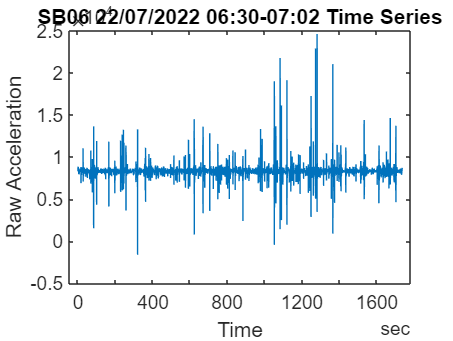

Ts = 1/Fs;

%Convert Wave Sample of Interest to TimeTable
WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);

%%TODO
%%Fix the time issue (~15 second offset by using retime)
%WaveTimeTable = retime(WaveTimeTable, 'regular', 'linear', 'SampleRate', Fs); 

%Plot raw signal 
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
title("SB06 22/07/2022 06:30-07:02 Time Series");
xlabel("Time");
ylabel("Raw Acceleration"); 

## Preprocess Vertical Acceleration Signal: Heave Only 

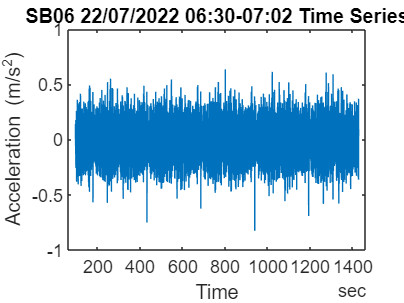

% Scale 
Heave = ( WaveTimeTable.Heave ) / 8192 * 9.807;
%Detrend 
Heave = detrend(Heave);
%Lowpass filter 
Heave = lowpass(Heave, 2, Fs);

%Plot Pre-processed signal 
plot(WaveTimeTable.Time, Heave);
title("SB06 22/07/2022 06:30-07:02 Time Series");
xlabel("Time");
ylabel("Acceleration (m/s^2)"); 

## Preprocess Vertical Acceleration: Roll, Pitch Sensor Fusion 

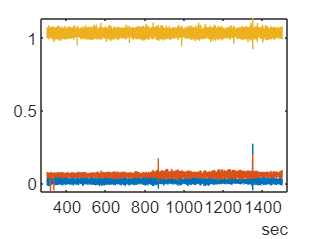

%Parameters 
gyroNoise = convangvel(0.49, 'deg/s', 'rad/s');
accNoise = 10*1/1000*9.807;
Fs = 100;

%Readings
accReading = [WaveTimeTable.Surge/8192, WaveTimeTable.Sway/8192, WaveTimeTable.Heave/8192];
gyroReading = [WaveTimeTable.Roll/65.5*(pi/(180)), WaveTimeTable.Pitch/65.5*(pi/(180)), WaveTimeTable.Yaw/65.5*(pi/(180))];

plot(WaveTimeTable.Time,accReading);

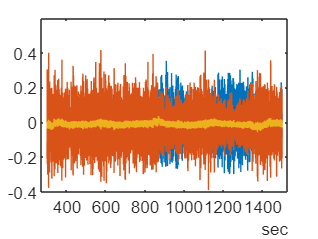

plot(WaveTimeTable.Time, gyroReading);


Fuse = imufilter('SampleRate', Fs, 'ReferenceFrame', 'NED'); %, "AccelerometerNoise", accNoise, "GyroscopeNoise", gyroNoise);

q = Fuse(accReading, gyroReading);

time = (0:1:size(accReading,1)-1)/Fs;

plot(time,eulerd(q,'ZYX','frame'))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

%Array initialised
accReading = zeros(180000, 3);
gyroReading = zeros(180000, 3);
accFilter = zeros(150000, 3);
gyroFilter = zeros(150000, 3);
VertAccArray = zeros(150002, 1);

 % Scale 
accReading = [WaveSampleTable.Surge/8192, WaveSampleTable.Sway/8192, WaveSampleTable.Heave/8192];
gyroReading = [WaveSampleTable.Roll/65.5*(1/(2*pi)), WaveSampleTable.Pitch/65.5*(1/(2*pi)), WaveSampleTable.Yaw/65.5*(1/(2*pi))];
[q, gyroReadingKF] = Fuse(accReading, gyroReading);
eulerAngles = eulerd(q,'XYZ','frame');

%Remove first 5 minutes 
accFilter = accReading(Fs*300:end, :);
gyroFilter = gyroReadingKF(Fs*300:end, :); 
orientationFilter = eulerAngles(Fs*300:end, :);

%Filter Accleration value - scale to m/s^2]
g = 9.81;
accFilter = accFilter.*g;

%Truncate time series to remove transient response
%Remove first 5 minutes 
accFilter = accReading(Fs*300:end, :);
gyroFilter = gyroReadingKF(Fs*300:end, :); 
orientationFilter = eulerAngles(Fs*300:end, :); 

VertAcc = detrend((sind(gyroFilter(:, 2)).*accFilter(:, 1) + sind(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 2) + cosd(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 3))) ;


## Stand Correction

%initialise arrays
%Stand Correction parameters
r = 0.90 %Approximate IMU elevation in m 
R = zeros(150000 + 2, 3);
R(:, 3) = R(:, 3) + r; %Matrix with relative height
omega = zeros(150000 + 2, 3);
alpha = zeros(150000 + 2, 3);
acc_buoy_pancake = zeros(150000, 3);

%Calculate Angular Acceleration and Velocity
r = 0.90 %Approximate IMU elevation in m 
R = zeros(length(gyroFilter), 3);

%Calculate angular velocity and acceleration 
omega(1:end, 2) = gyroFilter(:, 2); 
alpha(1:end -1, 2) = diff(omega(:, 2));
omega(1:end, 1) = gyroFilter(:, 1);
alpha(1:end -1, 1) = diff(omega(:, 1));

%relative acceleration of buoy to pancake
acc_buoy_pancake = cross(omega, cross(omega, R)) + cross(alpha, R);

%Surge correct: Subtract relative motion
accFilter = accFilter - acc_buoy_pancake;   

%Correct
VertAccCorrect = detrend((sind(gyroFilter(:, 2)).*accFilter(:, 1) + sind(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 2) + cosd(gyroFilter(:, 1)).*cosd(gyroFilter(:, 2)).*accFilter(:, 3)));

% %Plot stand correction
plot(WaveTimeTable.Time, VertAcc, WaveTimeTable.Time, VertAccCorrect);
title("SB06 22/07/2022 14:50-15:20 Impact Time Series");
xlabel("Time");
ylabel("Acceleration (m/s^2)"); 

## Impact Analysis

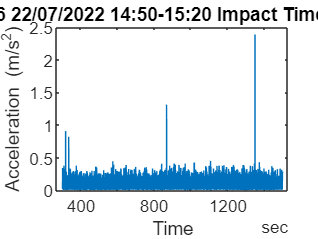

% Scale 
Surge = ( WaveTimeTable.Surge / 8192 ) * 9.807;
Sway =  ( WaveTimeTable.Sway / 8192 ) * 9.807;

%Detrend 
Surge = detrend(Surge);
Sway = detrend(Sway);

%Lowpass filter 
Surge = lowpass(Surge, 40, 100);
Sway = lowpass(Sway, 40, 100);

%Resultant Vector
ImpactVector = sqrt(Surge.^2 + Sway.^2);

%Plot Impact vectors
plot(WaveTimeTable.Time, ImpactVector);
title("SB06 22/07/2022 14:50-15:20 Impact Time Series");
xlabel("Time");
ylabel("Acceleration (m/s^2)"); 

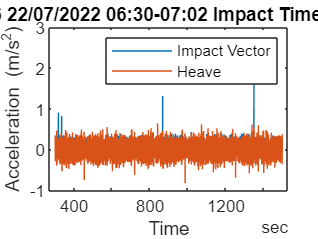


%Plot Impact vectors vs Heave
plot(WaveTimeTable.Time, ImpactVector, WaveTimeTable.Time, Heave);
title("SB06 22/07/2022 06:30-07:02 Impact Time Series");
xlabel("Time");
ylabel("Acceleration (m/s^2)"); 
legend("Impact Vector", "Heave");

## Spectral Analysis of single raw time series (acceleration) 

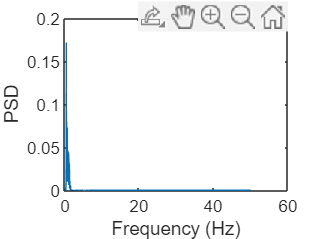

%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

[pxx, f] = pwelch(Heave, segmentLength, [], segmentLength, 100, "onesided", "psd"); 

%Plot Acceleration PSD 
plot(f, pxx);
xlabel('Frequency (Hz)');
ylabel('PSD');

## Integration to Displacement

%Tranform to the frequency domain 
y = fft(Heave);
y = fftshift(y);

%Double integration in the frequency domain

f1 = 0.15; %Lower corner frequency for half cosine taper
f2 = 0.20; %Upper frequency for half cosine taper
fc = 4; 

Nfft = length(y);

%frequency array 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -52.5000
  -52.4993
  -52.4985
  -52.4978
  -52.4970
  -52.4963
  -52.4955
  -52.4948
  -52.4940
  -52.4933


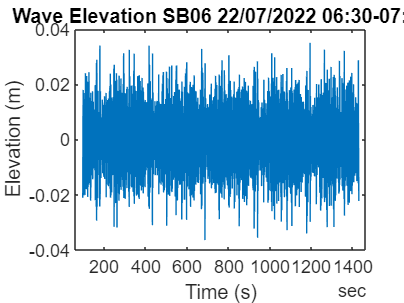

N = size(f, 1); 

%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);

for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 & f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1)))*(-1/(2*pi*f(i)).^2);
        end
            if f(i) > f2 & f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)).^2; 
            end
end

%Acceleration .* Rf
elevFFT = y.*Rf; 

%Elevation 
elev = ifft(fftshift(elevFFT)); 

%Remove 30s from each side 
sec_30 = Fs*30;

%scaling factor of 2 for actual wave height - discovered in wave tank
%testing 
elev = 2*real(elev);

elevLeakage = elev; 
%Plot Elevation with Spectral Leakage
plot(WaveTimeTable.Time, elev);
title("Wave Elevation SB06 22/07/2022 06:30-07:02")
xlabel('Time (s)')
ylabel('Elevation (m)')

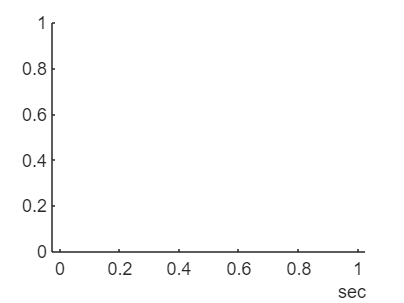

Error using plot
Vectors must be the same length.



elev = elev(sec_30:(end-sec_30));

%Plot elevation output 
timeSeries = WaveTimeTable.Time(ceil(sec_30):ceil((end-sec_30)-1));
plot(timeSeries, elev);

title("Wave Elevation SB06 22/07/2022 06:30-07:02")
xlabel('Time (s)')
ylabel('Elevation (m)')

%Plot elevation with spectral leakge and truncated elevation over
%eachother
plot(WaveTimeTable.Time, elevLeakage, timeSeries, elev);
legend("Full series", "Truncated series")
title("Wave Elevation SB06 22/07/2022 06:30-07:02")
xlabel('Time (s)')
ylabel('Elevation (m)')




## Impact vs Displacement Plot 

%Truncate Acceleration Signal 
sec_30 = Fs*30; 
ImpactVector = ImpactVector(sec_30:(end-sec_30));

%Plot elevation output 
timeSeries = WaveTimeTable.Time(sec_30:(end-sec_30));
yyaxis left;
plot(timeSeries, elev);
ylim([-3 3]);
ylabel('Elevation (m)');
yyaxis right;
plot(timeSeries, ImpactVector);
title("Wave Elevation and Collisions SB06 22/07/2022 06:30-07:02")
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
ylim([-12 12]);
hold off

## PSD Estimate (Welch's Method)

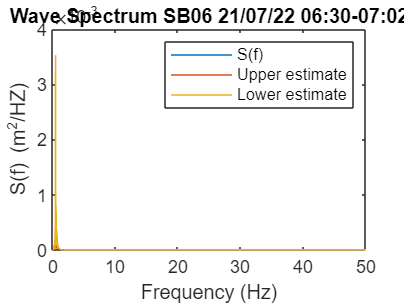

%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

[pxx, f, pxxc] = pwelch(elev, segmentLength, [], segmentLength, 100, "onesided", 'ConfidenceLevel', 0.90); 

pxx = pxx;
pxxc = pxxc;

%Plot Elevation PSD (Welch) 
plot(f, pxx, f, pxxc);
title("Wave Spectrum SB06 21/07/22 06:30-07:02");
xlabel('Frequency (Hz)');
ylabel('S(f) (m^2/HZ)');
legend('S(f)', 'Upper estimate', 'Lower estimate');


% % %Plot Elevation PSD (Periodogram)
% [pyy1, f] = periodogram(elev(1:1*segmentLength), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy2, f] = periodogram(elev(1*segmentLength:2*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy3, f] = periodogram(elev(2*segmentLength:3*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy4, f] = periodogram(elev(3*segmentLength:4*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy5, f] = periodogram(elev(4*segmentLength:5*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% 
% 
% plot(f, pyy1, f, pyy2, f, pyy3, f, pyy4, f, pyy5);
% title("Wave Spectrum SB06 22/07/22 06:30-07:02")
% xlabel('Frequency (Hz)')
% ylabel('S(f) (m^2/HZ)')
% legend("$\hat{S}(f)$: 16:50 - 16:55", "$\hat{S}(f)$: 16:55 - 17:00", "$\hat{S}(f)$: 17:00 - 17:05", "$\hat{S}(f)$: 17:05 - 17:10", "$\hat{S}(f)$: 17:10 - 17:15", 'Interpreter','latex')

## Doppler Correction

g = 9.807;
fobs = f; 

%Read in GPS Data
GPSDir = "C:\Users\uctsh\Documents\MATLAB\GPSData";
gpsfile = fullfile(GPSDir, "SB04_GPS_Local.txt"); 
%GPS Data
GPSData = readtable(gpsfile);

GPSData = GPSData(GPSData.timeSeriesCount == WaveSample, :);  

Unrecognized function or variable 'WaveSample'.


Lat = GPSData.Latitude;
Lon = GPSData.Longitude; 

dist = acos(cosd(90-Lat(1:end-1)) .* cosd(90-Lat(2:end)) + sind(90-Lat(1:end-1)) .* sind(90-Lat(2:end))) .* cosd(Lon(1:end-1)-Lon(2:end)) * 6371 * 1000;


U = dist/(seconds(WaveSampleTable.DateTimeUTC(end) - WaveSampleTable.DateTimeUTC(1)));

fin = fobs - (g - 4*pi.*fobs*U - sqrt(g^2 - 8*pi*g*fobs*U))./(-4*pi*U);

%Plot Elevation PSD (Welch) 
plot(fin, pxx, f, pxx);
title("Wave Spectrum SB06 21/07/22 06:30-07:02");
xlabel('Frequency (Hz)');
ylabel('S(f) (m^2/HZ)');
legend('S(f)', 'S(f) corrected');

## Extraction of wave parameters 

Credit: SWASH Model 

m=length(pxx);
%number of subintervals
m=m-1;
%length of the subinterval
Ax=(f(m+1)-f(1))/m;

%Integral I1 m0=int{E(f)df} I1
s=0;
s_lower = 0; 
s_upper = 0;

for i=2:m
 s=s+pxx(i); %sum(2,m) f(xi)
 s_lower=s_lower+pxxc(i, 1);
 s_upper = s_upper+pxxc(i, 2);
end

m0=0.5*Ax*(pxx(1)+2*s +pxx(m+1));
m0_lower = 0.5*Ax*(pxxc(1, 1)+2*s_lower +pxxc(m+1, 1));
m0_upper = 0.5*Ax*(pxxc(1, 2)+2*s_upper +pxxc(m+1, 2));

%Integral I2 m1=int{f*E(f)df} 
s=0;
s_lower = 0;
s_upper = 0;

%f=f*E(f)=f*mW
for i=2:m
 s=s+f(i)*pxx(i);
 s_lower = s_lower + f(i)*pxxc(i, 1); 
 s_upper = s_upper + f(i)*pxxc(i, 2); 
end

m1= 0.5*Ax*(f(1)*pxx(1)+2*s+f(m+1)*pxx(m+1));
m1_lower = 0.5*Ax*(f(1)*pxxc(1, 1)+2*s_lower+f(m+1)*pxxc(m+1, 1));
m1_upper = 0.5*Ax*(f(1)*pxxc(1, 2)+2*s_upper+f(m+1)*pxxc(m+1, 2));

Hm0 = 4*sqrt(m0);
Tm01 = m0/m1; 
Hm0_lower = 4*sqrt(m0_lower);
Hm0_upper = 4*sqrt(m0_upper);
